CT重建软件

丁昊妍  520021910379

生成Shepp-Logan模型

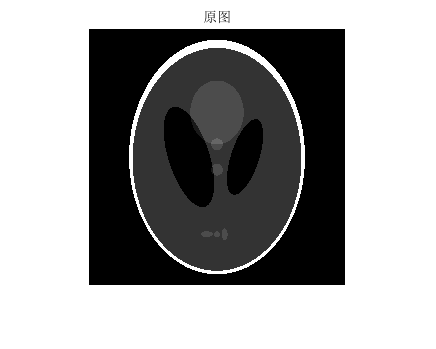

clc;clear;
M=256;
[P, E] = phantom('Modified Shepp-Logan', M); % 创建一个 shepp-logan 模型，原图像
figure
imshow(P) %原图像
title('原图');

解析法投影

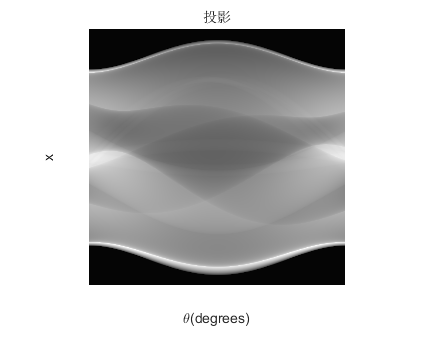

randon_row=M;
radonImg_Computerized=double(zeros(randon_row,180));
for i = 1:10 %计算每个椭圆
    rou = E(i,1);%灰度值
    a = E(i,2)*M/2;%椭圆横轴
    b = E(i,3)*M/2;%椭圆竖轴
    m = E(i,4)*M/2;%椭圆中心x
    n = E(i,5)*M/2;%椭圆中心y
    alpha = E(i,6)*pi/180;%椭圆横轴和x轴夹角
    for theta_degree =0:1:179 %计算每个角度
        theta = theta_degree*pi/180;
        a_theta_2 = a*a*((cos(theta-alpha))^2) + b*b*((sin(theta-alpha))^2);
        s = sqrt(m*m +n*n);
        if n == 0
            if m >= 0
                gamma =0;
            else
                gamma = pi;
            end
        else
            if m < 0
                gamma = atan(n/m) + pi;%二三象限
            else
                gamma = atan(n/m);%一四象限
            end
        end
        
        for j = 0:1:randon_row-1 %计算每个P
            t0 = j-0.5*randon_row;
            t = t0 -s*cos(gamma-theta);
            if t*t <= a_theta_2
                radonImg_Computerized(j+1,theta_degree+1) = radonImg_Computerized(j+1,theta_degree+1)...
                    + ((2*255*rou*a*b)/a_theta_2)*sqrt(a_theta_2 - t*t);
            end
        end
    end
end

figure
radonImg_Computerized1 = imresize(radonImg_Computerized, [256,256]);
imshow(radonImg_Computerized1,[])%,'InitialMagnification', 'fit')
xlabel('\theta(degrees)')
ylabel('x')
title('投影');

傅里叶变换反投影

filter_choose的值，默认为1，即使用滤波器，若不想使用滤波器可改为0。

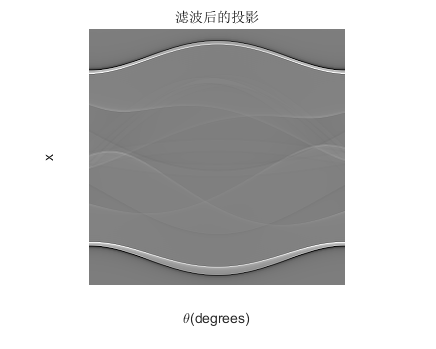

sensor_length = M;%投影器数量
filter_choose = 1;%选择是否用滤波器，1为用，0为不用
projection = radonImg_Computerized;
pixelsize(1) = M;
pixelsize(2) = M;
Img = fbp(projection,filter_choose,sensor_length,pixelsize);

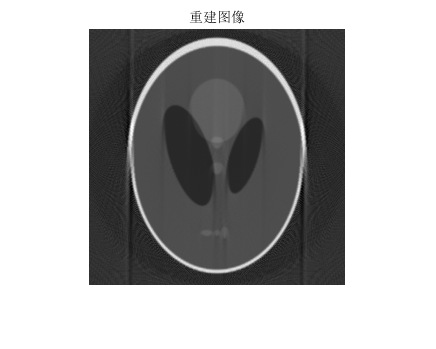

figure
imshow(Img,[]);
title('重建图像');

扇形扫描

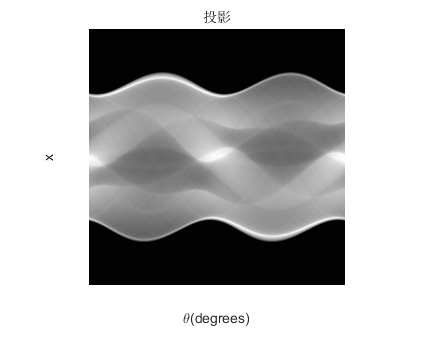

img = P;
filter_choose = 1;%选择是否用滤波器，1为用，0为不用
beta = 0:1:359;%射线源与探测器旋转角度，默认逆时针旋转
[M,~] = size(img);
dS = 1;%探测器在物体中心线处的间隔（探测器实际上间隔会大于dS）
rayNum = ceil(sqrt(2)*M);%探测器数=射线数
distance = 2*M;%射线源到物体中心的距离，SOD

R = Projection(img,beta,distance,rayNum,dS);%正投影，因为用了interp2比较慢
figure
R1 = imresize(R, [256,256]);
imshow(R1,[]);
xlabel('\theta(degrees)');
ylabel('x');
title('投影');

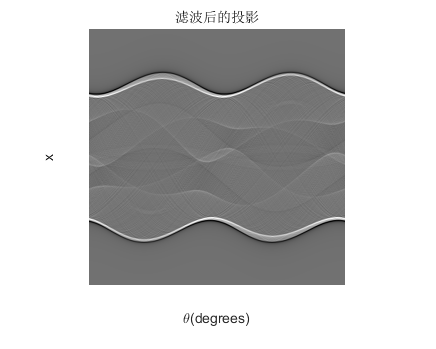


[recon] = FanBeamFBP(M,M,beta,R,rayNum,dS,distance,filter_choose);%滤波反投影

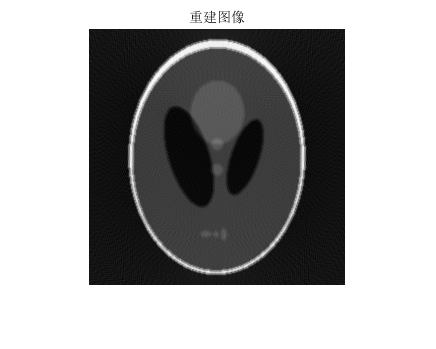

figure
imshow(recon,[]);
title('重建图像');

读入图像

默认选择提供的素材CT图片，可以更换其他图片

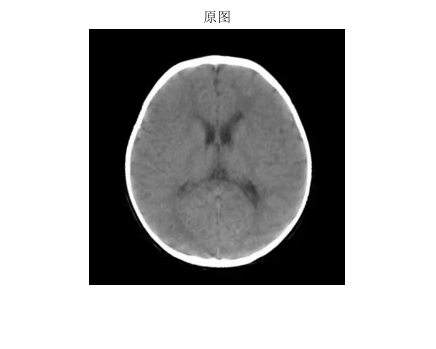

clc;clear;
M=256;
%显示图像，选择imtool工具可有效调节窗宽窗位
P = imread('ct.jpg');%使用默认图片进行测试，可以更换其他图片
P = imresize(P, [M,M]);
P = rgb2gray(P);
P = im2double(P); %转换成double
figure
imshow(P);
title('原图');

数字积分法

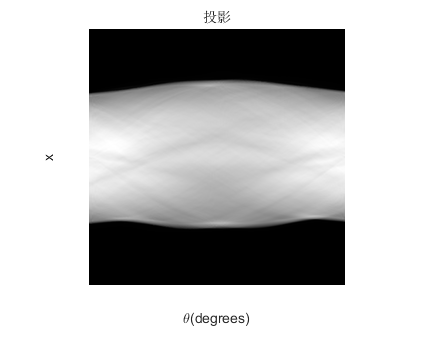

num_degrees = 180;
%确定发射器和接收器的位置
img_longest_edge = max(size(P,1), size(P,2));%图像最长边
sensor_length = ceil(img_longest_edge*sqrt(2))+2;%投影器数量
radonImg = zeros(sensor_length, num_degrees);
%projection_1d = zeros(sensor_length,1);


for theta_degree = 90:1:num_degrees+90-1
    theta = theta_degree*pi/180;
    projection_1d = zeros(sensor_length,1);
    %发射器中点
    mid_Trm_x = 0.5*(sensor_length - 2) * cos(theta + pi);
    mid_Trm_y = 0.5*(sensor_length - 2) * sin(theta + pi);
    %发射器
    Trm(1,1) = mid_Trm_x + 0.5*sensor_length*cos(0.5*pi+theta);
    Trm(2,1) = mid_Trm_y + 0.5*sensor_length*sin(0.5*pi+theta);
    for i = 2:1:sensor_length
        Trm(1,i) = Trm(1,i-1) - cos(0.5*pi+theta);
        Trm(2,i) = Trm(2,i-1) - sin(0.5*pi+theta);
    end
    
    %接收器中点
    mid_Rcv_x = 0.5*(sensor_length) * cos(theta);
    mid_Rcv_y = 0.5*(sensor_length) * sin(theta);
    %接收器
    Rcv(1,1) = mid_Rcv_x + 0.5*sensor_length*cos(0.5*pi+theta);
    Rcv(2,1) = mid_Rcv_y + 0.5*sensor_length*sin(0.5*pi+theta);
    for i = 2:1:sensor_length
        Rcv(1,i) = Rcv(1,i-1)-cos(0.5*pi+theta);
        Rcv(2,i) = Rcv(2,i-1)-sin(0.5*pi+theta);
    end

    %投影，这个角度下所有的投影值
    for i = 1:1:sensor_length
        projection_1d(i)=0;
        %计算相交比例alpha值范围
        [min_alpha, max_alpha, flag_intersection] = Caculate_range_alpha(i,Trm,Rcv,P);
        if flag_intersection == 0 %没有交点，或者仅有一个点的交点（而不是线段），所以投影为0
            continue;
        end
        %计算射线与图像相交的m,n范围
        [intersection_n_min, intersection_n_max, intersection_m_min, intersection_m_max] = Calculate_range_index_image(i, Trm, Rcv, P, min_alpha, max_alpha);
        
        %求解alpha_x, alpha_y
        if mod(theta_degree, 90)~=0
            %求alpha_x
            sizeof_alpha_x = round(intersection_n_max-intersection_n_min+1);
            alpha_x = zeros(sizeof_alpha_x,1);
            for k = 0:1:sizeof_alpha_x-1
                x_position = intersection_n_min + k - size(P,2)/2;
                alpha_x(k+1) = (x_position -Trm(1,i))/(Rcv(1,i)-Trm(1,i));
            end           
            %求alpha_y
            sizeof_alpha_y = round(intersection_m_max-intersection_m_min+1);
            alpha_y = zeros(sizeof_alpha_y,1);
            for k = 0:1:sizeof_alpha_y-1
                y_position = size(P,1) / 2 - (intersection_m_min + k);
                alpha_y(k+1) = (y_position -Trm(2,i))/(Rcv(2,i)-Trm(2,i));
            end
            %合并
            sizeof_alpha = sizeof_alpha_x + sizeof_alpha_y;
            alpha = [alpha_x; alpha_y];
            alpha = sort(alpha);%, alpha + sizeof_alpha);%升序排序
        elseif mod(theta_degree, 180) == 0%平行x轴
            %求alpha_x
            sizeof_alpha_x = round(intersection_n_max-intersection_n_min+1);
            alpha_x = zeros(sizeof_alpha_x,1);
            for k = 0:1:sizeof_alpha_x-1
                x_position = intersection_n_min + k - size(P,2)/2;
                alpha_x(k+1) = (x_position -Trm(1,i))/(Rcv(1,i)-Trm(1,i));
            end           
            %求alpha
            sizeof_alpha = sizeof_alpha_x;
			alpha = alpha_x;
			alpha = sort(alpha);%, alpha + sizeof_alpha);
        else
            %求alpha_y
            sizeof_alpha_y = round(intersection_m_max-intersection_m_min+1);
            alpha_y = zeros(sizeof_alpha_y,1);
            for k = 0:1:sizeof_alpha_y-1
                y_position = size(P,1) / 2 - (intersection_m_min + k);
                alpha_y(k+1) = (y_position -Trm(2,i))/(Rcv(2,i)-Trm(2,i));
            end
            sizeof_alpha = sizeof_alpha_y;
			alpha = alpha_y;
			alpha = sort(alpha);%, alpha + sizeof_alpha);
        end

        projection_1d(i) = Calculate_projection_oneValue(i, Trm, Rcv, P, sizeof_alpha, alpha);
    end
    
    for m = 1:1:size(radonImg,1)
        radonImg (m, theta_degree-89) = projection_1d(m);
    end
    
end

figure
radonImg1 = imresize(radonImg, [256,256]);
imshow(radonImg1,[]);
title('投影');
xlabel('\theta(degrees)')
ylabel('x')

傅里叶变换反投影

filter_choose的值，默认为1，即使用滤波器，若不想使用滤波器可改为0。

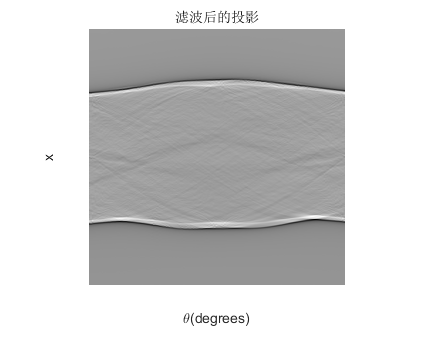

projection = radonImg;
filter_choose = 1;%选择是否用滤波器，1为用，0为不用
pixelsize(1) = size(P,1);
pixelsize(2) = size(P,2);
Img = fbp(projection,filter_choose,sensor_length,pixelsize);

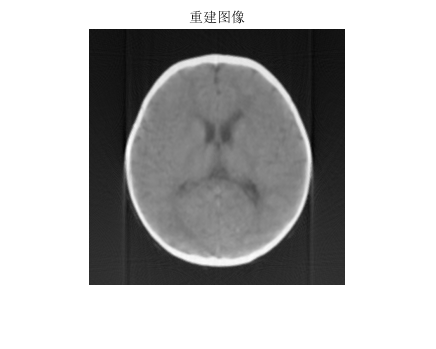

figure
Img1 = imresize(Img, [256,256]);
imshow(Img1,[]);
title('重建图像');

扇形扫描

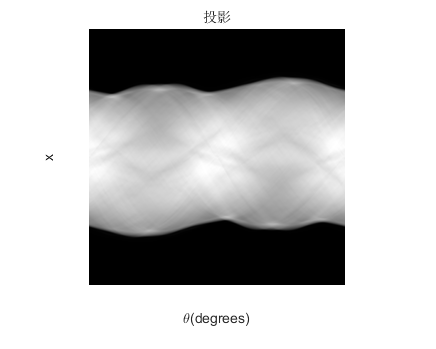

img = P;
beta = 0:1:359;%射线源与探测器旋转角度，默认逆时针旋转
[M,~] = size(img);
dS = 1;%探测器在物体中心线处的间隔（探测器实际上间隔会大于dS）
rayNum = ceil(sqrt(2)*M); %探测器数=射线数
distance = 2*M; %射线源到物体中心的距离，SOD

R = Projection(img,beta,distance,rayNum,dS);%正投影，因为用了interp2比较慢
figure
R1 = imresize(R, [256,256]);
imshow(R1,[]);
xlabel('\theta(degrees)');
ylabel('x');
title('投影');

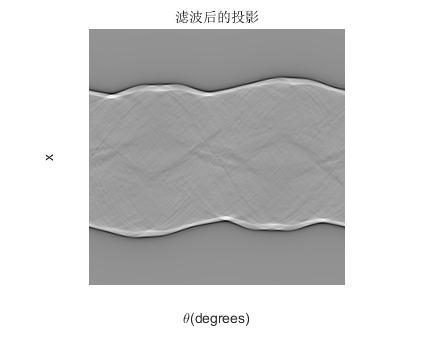


[recon] = FanBeamFBP(M,M,beta,R,rayNum,dS,distance,filter_choose);%滤波反投影

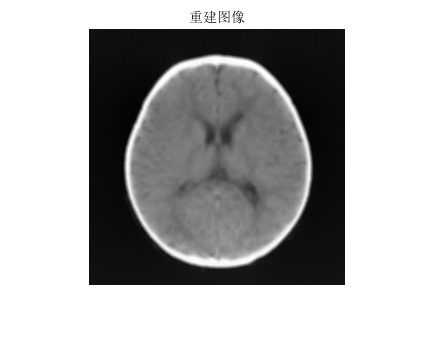

figure
imshow(recon,[]);
title('重建图像');

function u = U(D,x,y,beta)%公式中的U
    u = (D+x*sin(beta)-y*cos(beta))/D;
end

function proj = Projection(img, beta,distance,rayNum,dS)%正投影过程
    proj = zeros(rayNum, length(beta));
    [M,~] = size(img);
    M2 = (M-1)/2;
    [X, Y] = meshgrid(-M2 : 1 : M2); %图片坐标系重定位，以图像中心为(0,0)
    ray_x = -(rayNum-1)/2 * dS:dS:(rayNum-1)/2 * dS;%各光线在物体中心坐标系中与射线源中心线垂直线上的各值，dS为各探测器在该线上的间隔
    CY = -M2*sqrt(2):1:M2*sqrt(2);%垂直x轴线采样点的y,图像为正方形且采样间隔为1，因此设采样点数为根号2*M+1
    CX = zeros([1,length(CY)]);%垂直x轴线采样点的x
    for i = beta%360角全投影,默认逆时针旋转
        proj_1 = zeros(rayNum,1);%一个角度的投影
        r = deg2rad(i);%角度转弧度
        CX_1 = CX.*cos(-r)+CY.*sin(-r);
        CY_1 = CY.*cos(-r)-CX.*sin(-r);%射线源旋转i度后采样点跟着旋转
        for j = 1:length(ray_x)%每个角度有ray_x根线
            gamma = atan(ray_x(j)/distance);%gamma角，即射线与穿过源射线的夹角
            theta = r+gamma;%cos(theta)*x+sin(theta)*y=t中的theta
            t = (distance*ray_x(j))/sqrt(distance*distance+ray_x(j)*ray_x(j));%cos(theta)*x+sin(theta)*y=t中的t
            bias_x = t*cos(theta);%扇形束采样点的x偏置
            bias_y = t*sin(theta);%扇形束采样点的y偏置
            CX_real = CX_1.*cos(-gamma)+CY_1.*sin(-gamma)+bias_x;
            CY_real = CY_1.*cos(-gamma)-CX_1.*sin(-gamma)+bias_y;%采样点旋转gamma角并加上偏置得到射线采样点
            inter = interp2(X, Y, img, CX_real, CY_real, 'linear',0)';%线性插值得到各采样点的值,如果可以最好不要使用interp函数，很慢
            proj_1(j) = sum(inter,1); %#ok<UDIM> 
        end
        proj(:,i+1)=proj_1;        
        %str = ['扫描进度：',num2str(round(i/359*100)),'%'];
        %disp(str)
    end
end

function [recon] = FanBeamFBP(sizeM,sizeN,beta,R,rayNum,dS,distance,filter_choose)%反投影过程
    M = sizeM;%重建图像的行数
    N = sizeN;%重建图像的列数
    ray_x = -(rayNum-1)/2 * dS:dS:(rayNum-1)/2 * dS;
    ray_x = ray_x';
    weight_d = ones(rayNum,1).*distance;
    weight = weight_d./(sqrt(weight_d.*weight_d+ray_x.*ray_x));%得到权重
    clear weight_d;
    l = length(ray_x);
    clear ray_x;
    for i = 1:length(beta)
        R(:,i) = R(:,i).*weight;%投影加权
    end
    clear weight;
    if filter_choose == 1
        t = linspace(-N/2,N/2-1,N);
        filt = 0.0085*(sinc(t)/2-sinc(t/2).^2/4);%得到滤波的卷积核
        p = R;
        R = zeros(l+2*N,360);
        R(N+1:l+N,:) = p;
        for n = 1:360
            temp(:,n) = conv(R(:,n),filt); %#ok<AGROW> 
        end
        R = temp(3*M/2:3*M/2+l,:);%投影滤波
        figure
        R_filt1 = imresize(R, [256,256]);
        imshow(R_filt1,[]);
        xlabel('\theta(degrees)');
        ylabel('x');
        title('滤波后的投影');
    end
    clear p;
    recon = zeros([M,N]);%重建图像
    M2 = (M-1)/2;
    dbeta = deg2rad(1);
    for i = beta%射线源旋转每一个角度
        r = deg2rad(i);%角度转弧度
        for x = 1:M
            for y = 1:N%对于重建图像中的每一个点
                sp = distance*((y-M2-1)*cos(r)+(x-M2-1)*sin(r))/(distance+(y-M2-1)*sin(r)-(x-M2-1)*cos(r));
                %得到s'，这里的推导可以试着自己推一推，过(x,y)和射线源的点和D‘2(该线随β变化而变化)的交点与O连接线段的长度。
                % 再注意：这段循环中的x和y并不是正常的x和y，x表示行数而y表示列数，与我们习惯中的x和y的意义相反，
                % 因此推得公式的x，y要互换
                if (sp >= -(l-1)/2)&&(sp<=(l-1)/2)%若s 没有超出探测器的范围
                    isp = ceil(sp); sp0 = isp-sp;
                    proj_sp = (1-sp0)*R(isp+(l-1)/2+1,i+1)+sp0*R(isp+(l-1)/2,i+1);
                    %根据s 的值用他前后的射线投影为他插值，这里没用interp1，能够很大程度上加快运行速度
                    recon(x,y) = recon(x,y)+dbeta*(1/2*power(U(distance,(y-M2-1),(x-M2-1),r),2))*proj_sp;%重建图像上的像素点
                end
            end
        end
        %str = ['重建进度：',num2str(round(i/359*100)),'%'];
        %disp(str)
    end
end


%% 数字积分法函数
function [min_alpha, max_alpha, flag_intersection]  = Caculate_range_alpha(i,Trm,Rcv,P)%计算alpha范围
    %确定图像位置
    P_col = size(P,2);
    P_row = size(P,1);
    img_x_min = -0.5*P_col;
    img_y_min = -0.5*P_row;
    img_x_max = img_x_min + P_col;
    img_y_max = img_x_min + P_row;
    min_alpha_x = 1.0;
    min_alpha_y = 1.0;
    max_alpha_x = 0.0;
    max_alpha_y = 0.0;
    if (Rcv(1,i)-Trm(1,i))~=0 %不竖直
        min_alpha_x = min((img_x_min - Trm(1,i)) / (Rcv(1,i) - Trm(1,i)),...
			(img_x_max - Trm(1,i)) / (Rcv(1,i) - Trm(1,i)));
		max_alpha_x = max((img_x_min - Trm(1,i)) / (Rcv(1,i) - Trm(1,i)),...
			(img_x_max - Trm(1,i)) / (Rcv(1,i) - Trm(1,i)));
    end
    if ((Rcv(2,i) - Trm(2,i)) ~= 0)%不平行
		min_alpha_y = min((img_y_min - Trm(2,i)) / (Rcv(2,i) - Trm(2,i)),...
			(img_y_max - Trm(2,i)) / (Rcv(2,i) - Trm(2,i)));
		max_alpha_y = max((img_y_min - Trm(2,i)) / (Rcv(2,i) - Trm(2,i)),...
			(img_y_max - Trm(2,i)) / (Rcv(2,i) - Trm(2,i)));
    end
        
    min_alpha = max([min_alpha_x, min_alpha_y, 0.0]);
    max_alpha = min([max_alpha_x, max_alpha_y, 1.0]);

    flag_intersection = 1;
    if(min_alpha >= max_alpha)
        flag_intersection = 0;
    end
end

 
function [intersection_n_min, intersection_n_max, intersection_m_min, intersection_m_max] = Calculate_range_index_image(i, Trm, Rcv, P, min_alpha, max_alpha)
    %确定图像位置
    P_col = size(P,2);
    P_row = size(P,1);
    img_x_min = -0.5*P_col;
    img_y_min = -0.5*P_row;
    img_x_max = img_x_min + P_col;
    img_y_max = img_x_min + P_row;
    
    if Trm(1,i) < Rcv(1,i)
        intersection_n_min = (P_col) - (img_x_max - min_alpha * (Rcv(1,i) - Trm(1,i)) - Trm(1,i));
		intersection_n_max = -1 + (Trm(1,i) + max_alpha * (Rcv(1,i) - Trm(1,i)) - img_x_min);
    else
        intersection_n_min = (P_col) - (img_x_max - max_alpha * (Rcv(1,i) - Trm(1,i)) - Trm(1,i));
		intersection_n_max = -1 + (Trm(1,i) + min_alpha * (Rcv(1,i) - Trm(1,i)) - img_x_min);
    end
    
    %intersection_n_min = floor(intersection_n_min);
    %intersection_n_max = ceil(intersection_n_max);    
    
    if Trm(2,i) < Rcv(2,i)
        intersection_m_min = (P_col) - (Trm(2,i) + max_alpha * (Rcv(2,i) - Trm(2,i)) - img_y_min);
		intersection_m_max = img_y_max - min_alpha * (Rcv(2,i) - Trm(2,i)) - Trm(2,i) - 1;
    else
        intersection_m_min = (P_col) - (Trm(2,i) + min_alpha * (Rcv(2,i) - Trm(2,i)) - img_y_min);
		intersection_m_max = img_y_max - max_alpha * (Rcv(2,i) - Trm(2,i)) - Trm(2,i) - 1;
    end
    
    %intersection_m_min = floor(intersection_m_min);
    %intersection_m_max = ceil(intersection_m_max);
    
end

function projection = Calculate_projection_oneValue(i, Trm, Rcv, P, sizeof_alpha, alpha)
    total_TR_length = sqrt((Trm(1,i)-Rcv(1,i))^2+(Trm(2,i)-Rcv(2,i))^2);
    projection = 0.0;
    P_col = size(P,2);
    P_row = size(P,1);
    for k=2:1:sizeof_alpha
        length_little_route = (alpha(k)-alpha(k-1))*total_TR_length;
        mid_alpha = 0.5*(alpha(k)+alpha(k-1));
        M_pixel(1) = Trm(1,i) + mid_alpha*(Rcv(1,i)-Trm(1,i));
        M_pixel(2) = Trm(2,i) + mid_alpha*(Rcv(2,i)-Trm(2,i));
        
        n_pixel = floor(M_pixel(1) + 0.5 * P_col);
		n_pixel = max(0, n_pixel);
		n_pixel = min(n_pixel, P_col - 1);

		m_pixel = floor(0.5 * P_row - M_pixel(2));
		m_pixel = max(0, m_pixel);
		m_pixel = min(m_pixel, P_row - 1);
        
		grayscale = P(m_pixel+1, n_pixel+1);
		projection = projection + length_little_route * grayscale;
    end 
end